# Linearyzacja

#### Mateusz Wójcik, 11.12.2024

Celem laboratorium jest zapoznanie się z metodą linearyzacji oraz symulacji numerycznej prostego obiektu nieliniowego zbiornika, którym zajmowano się na wcześniejszych zajęciach laboratoryjnych. Model zbiornika przedstawiono na rysunku poniżej:

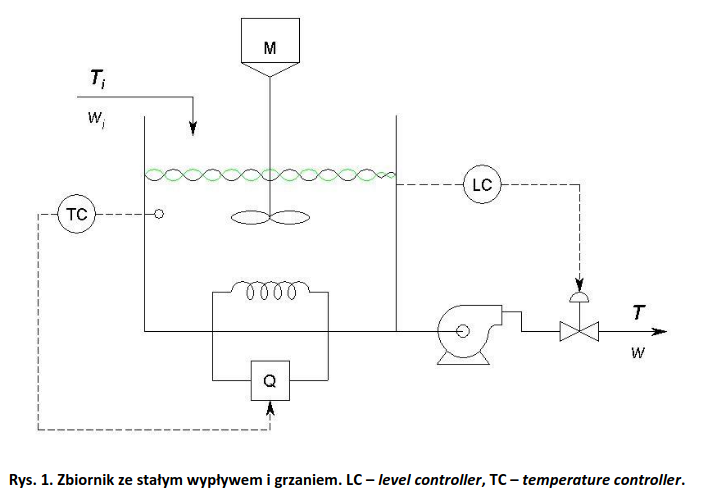

W trakcie tych zajęć skupiono się na wyznaczaniu stanu ustalonego i linearyzacji, dlatego do opisu matematycznego modelu wykorzystano wcześniej przygotowane w konspekcie funkcje.

clear

Laboratoria rozpoczęto od zdefiniowania stałych oraz zasymulowaniu obiektu przy użyciu metody rozwiązywania równań różniczkowych Rungego-Kutty, którą poznano w serii wcześniejszych zajęć laboratoryjnych.

#### Definiowanie zmiennych wejściowych:

T0 = 293;
V0= 0.04;
w = 0.4;
wi = 0.4;
Q = 12000;
Ti = 293;

W celu wykorzystania funkcji ode45, w osobnym pliku o nazwie *zbiornik_stan.m *wykorzystano gotowy skrypt, który zawarty był w konspekcie i którego zadaniem jest opisanie procesu zachodzącego w modelu. Skrypt przedstawiono poniżej:

function dx = zbiornik_stan(t,x,wi,w,Ti,Q)
% Argumenty wejściowe:
% t - czas
% x - wektor stanu układu
% wi - dopływ
% w - wypływ
% Ti - temperatura cieczy dopływającej
% Q - moc dostarczana (grzanie)
%----------------------------- zmienne stanu ------------------------------
x1 = x(1); % objętość
x2 = x(2); % temperatura
%------------------------------- parametry --------------------------------
C = 4200; % ciepło właściwe [J/(Kg*K)]
ro = 1000; % gęstość [kg/m3]
%%---------------------------- równania stanu -----------------------------
dx1 = 1 / ro * (wi-w);
dx2 = wi * (Ti - x2) / (ro * x1) + Q / (ro * x1 * C);
dx = [dx1;dx2]; % pochodne stanu
end

#### Przeprowadzenie symulacji dla stałych współczynników:

Mając wszystkie składowe, przeprowadzono pierwszą symulację, a jej wyniki przedstawiono na wykresach poniżej:

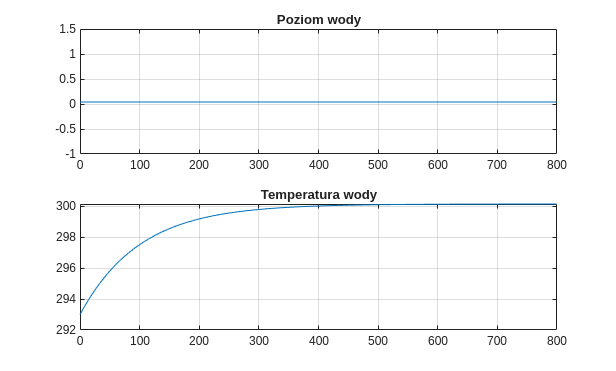

[t,xx] = ode45(@zbiornik_stan, [0:799], [V0,T0], [], wi, w, Ti, Q);

figure()
subplot(211)
plot(t,xx(:,1))
grid on
title("Poziom wody")
subplot(212)
plot(t,xx(:,2))
grid on
title("Temperatura wody")

W celu linearyzacji modelu interesujące jest znalezienie punktu, dla którego proces będzie znajdował się w stanie równowagi. Jeśli w stanie równowagi wszystkie wejścia pozostają stałe przez okres dłuższy niż największe opóźnienie czasowe występujące w układzie, to proces znajduje się w stanie ustalonym. Wokół stanu ustalonego linearyzuje się zazwyczaj modele układów nieliniowych. Wartości wyjść w stanie ustalonym można wyliczyć analitycznie z równań stanu (w stanie ustalonym zerują się pochodne), analitycznie przy użyciu transmitancji i twierdzenia o wartości granicznej:


$$y_u = \lim_{s \rightarrow 0} sY(s)$$


W Matlabie można to wykonać numerycznie przy pomocy funkcji trim, która przyjmuje jednak tylko modele zapisane w Simulinku. W tym celu stworzono model przy użyciu ***s-funkcji***, która przestaje być aktualnie wspierana przez Matlab, ale wciąż działa, i wprowadzono dla niej alternatywne rozwiązanie (przejście z levelu -1 na level -2). Model z Simulinka przedstawiono na Rysunku poniżej:

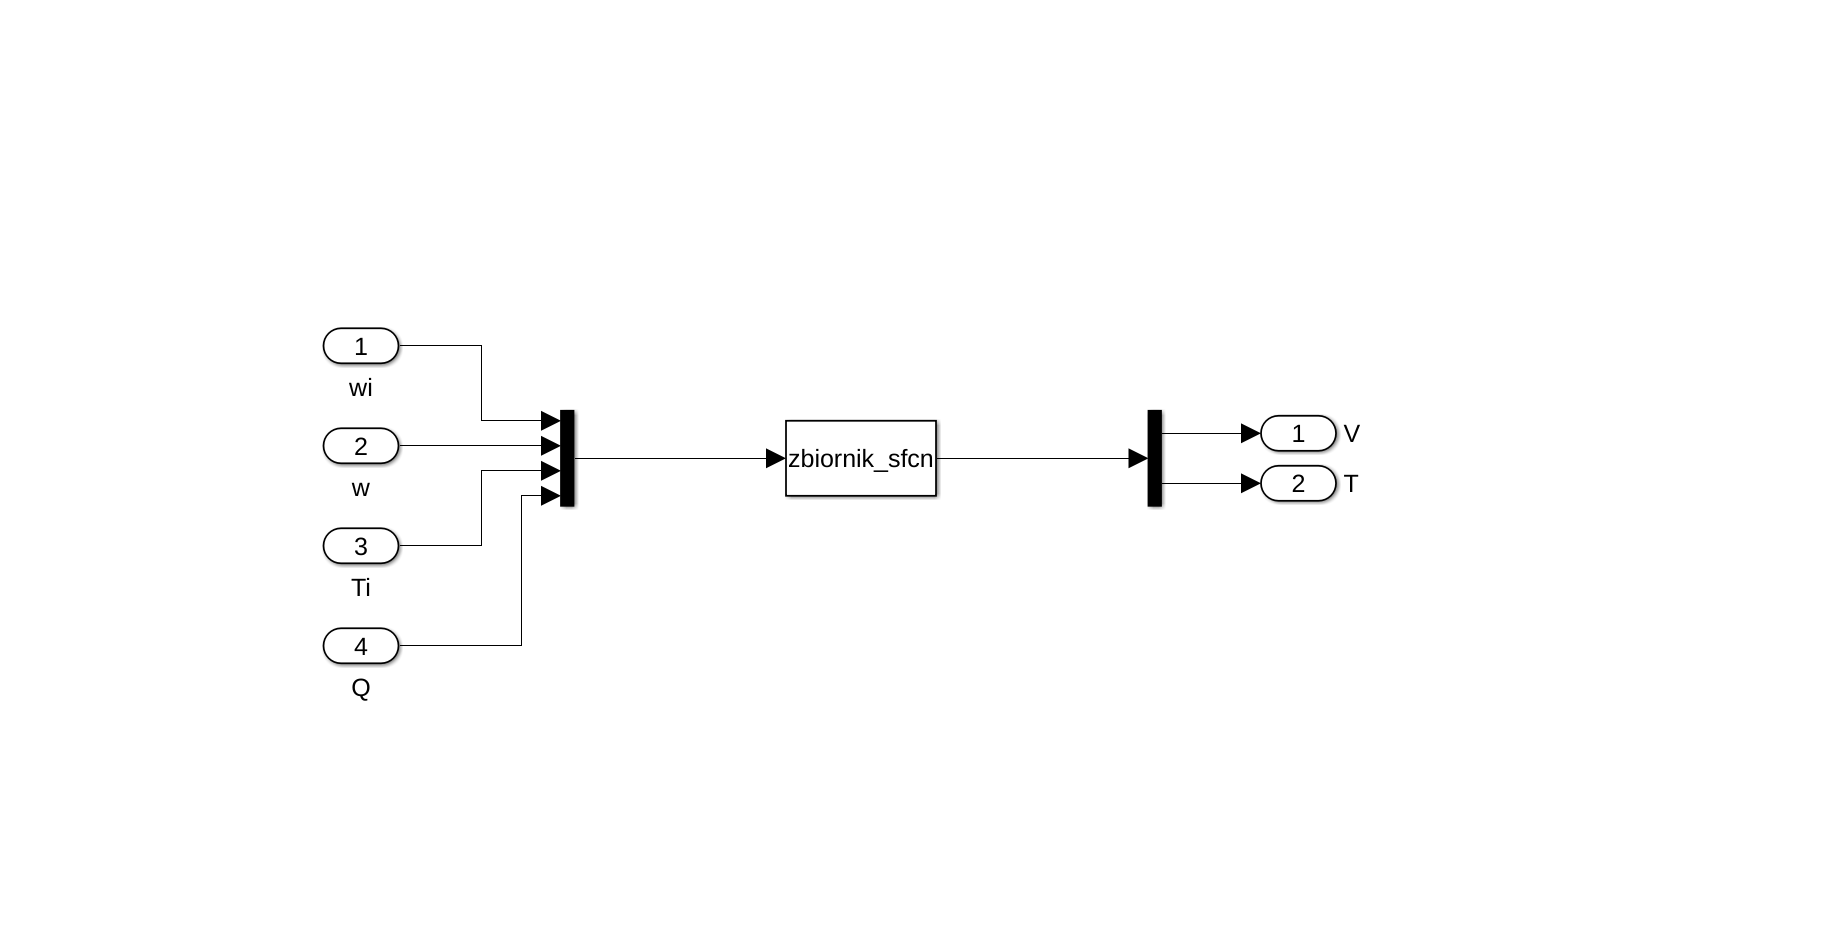

Widać na nim bloczek *s-funkcji, *który skonfigurowano, podając drugi skrypt.Kod ten również został pod any w konspekcie. Jego celeme jest umożliwienie s-funkcji korzystania z skryptu zbiornik_stan.m, który wykorzystano do opisu modelu. Kod pliku zbiornik_sfcn.m przedstawiono poniżej:

function [sys,x0,str,ts]=zbiornik_sfcn(t,x,u,flag,V0,T0)
    switch flag
        case 0 % inicjalizacja
            str = [];
            ts = [0 0];
            s = simsizes;
            s.NumContStates = 2; % liczba stanów ciągłych
            s.NumDiscStates = 0; % liczba stanów dyskretnych
            s.NumOutputs = 2; % liczba wyjść
            s.NumInputs = 4; % liczba wejść
            s.DirFeedthrough = 0; % wejście nie przenosi się bezpośrednio na wyjście
            s.NumSampleTimes = 1; % czas próbkowania
            sys = simsizes(s);
            x0 = [V0, T0];
        case 1 % pochodne
            wi = u(1);
            w = u(2);
            Ti = u(3);
            Q = u(4);
            sys = zbiornik_stan(t,x,wi,w,Ti,Q);
        case 3 % wyjście
            sys = x;
        case {2 4 9}
            sys =[];
        otherwise
            error(['unhandled flag =',num2str(flag)]);
    end
end

Po zdefiniowaniu odpowiedniego modelu w Simulinku, wykorzystano funkcję trim, w celu poszukiwania stanu ustalonego. W tym celu wzorując się przykładowym kodem podanym w konspekcie zdefiniowano parametry wejściowe do funkcji trim i wywołano ją.

X0=[0.04;303]; % wektor stanu (w stanie ustalonym)
U0=[0.4;0.4;293;12000]; % wektor wejść [wi,w,Ti,Q]
Y0=[0.04;303]; % wektor wyjść (chcemy aby objętość cieczy w zbiorniku była stała i wynosił 0.04 m3
%X0,U0,Y0 stanowią punkt wokół którego funkcja trim stara się znaleźć stan ustalony. Można również
%zablokować wybrane wartości wejść, wyjść i stanu aby pozostały stałe (tzn. aby funkcja trim ich nie
%zmieniała). Służą do tego wektory IX,IU,IY, np.:

IX=[]; % wartości stanu nie są blokowane
IU=[1;2;3]; % pierwsza (wi), druga (w) i trzecia zmienna wejściowa (Ti) jest zablokowana (na wartościach odpowiednio: 0.4,0.4,293)
IY=[1;2]; % pierwsza (V=0.04) i druga (T=303) zmienna wyjściowa jest zablokowan
V_0 = 0.04;
T_0 = 293;
[x,u,y,dx] = trim('zbiornik_sys',X0,U0,Y0,IX,IU,IY)

x =     0.1477
  302.8920


u = 1.0e+04 *

    0.0000
    0.0000
    0.0293
    1.2000


y =     0.1477
  302.8920


dx = 1.0e-11 *

    0.0000
   -0.1394


Przy pierwszym użyciu funkcja trim zwróciła ten sam wynik, jest to zachowanie, które  sugeruje, że funkcja napotkała błąd, o czym można dowiedzieć się z dokumentacji. W celu uzyskania poprawnych wyników zdecydowano się na zmianę parametrów funkcji trim, a dokładniej precyzji obliczenia punktu równowagi. Zwiększając precyzję do poziomu $10^{-5}$ otrzymano następujące rezultaty:

[x,u,y,dx] = trim('zbiornik_sys',X0,U0,Y0,IX,IU,IY, [], [], [1,1e-5])

f-COUNT     MAX{g}         STEP  Procedures
    8    0.0285714            1   
   17    0.0328252          0.5  Hessian modified twice 
   31    0.0330837       0.0156  Hessian modified twice 
   47    0.0331525      0.00391  Hessian modified twice 
   60    0.0337081       0.0312  Hessian modified twice 
   72    0.0348969       0.0625  Hessian modified twice 
   83    0.0375005        0.125  Hessian modified twice 
   96    0.0381962       0.0312  Hessian modified twice 
  109    0.0388893       0.0312  Hessian modified twice 
  128    0.0389003     0.000488  Hessian modified twice 
  137    0.0516188          0.5  Hessian modified twice 
  148    0.0551484        0.125  Hessian modified twice 
  161    0.0560295       0.0312  Hessian modified twice 
  175    0.0564724       0.0156  Hessian modified twice 
  188    0.0573535       0.0312  Hessian modified twice 
  198    0.0646292         0.25  Hessian modified twice 
  212    0.0650589       0.0156  Hessian modified twice 
  220    

x =     0.0400
  303.0000


u = 1.0e+04 *

    0.0000
    0.0000
    0.0293
    1.6800


y =     0.0400
  303.0000


dx = 1.0e-14 *

         0
    0.9173


Obliczony teraz punkt pracy zgadza się z tym punktem ustalonym, który obliczony został analitycznie na wcześniejszych zajęciach. Następnie możliwe zostało przystąpienie do wykonania linearyzacji funkcji w punkcie. W tym celu skorzystano z funkcji Matlba - **linmod**, do której podano model z Simulinka oraz wektor wejść i stanu w stanie ustalonym.

[A,B,C,D] = linmod('zbiornik_sys', x, u);

Wynikiem funkcji linmod są macierze opisujące przestrzeń stanu, na których podstawie możliwe jest wyznaczanie transmitancji w zależności od jednej z czterech zmiennych wejściowych: (wi, w, Ti, Q). Oczywiście otrzymano transmitancję zarówno na objętość cieczy w zbiorniku jak i temperaturę, stąd dwie transmitancje.

[licz,mian] = ss2tf(A,B,C,D,1);
printsys(licz,mian)

 
num(1)/den = 
 
   0.001 s + 1e-05
   ---------------
     s^2 + 0.01 s
 
num(2)/den = 
 
   -0.25 s - 1.3344e-15
   --------------------
       s^2 + 0.01 s


Wykorzystując funkcję **lsim** przystąpiono do wykreślenia wykresu dla zlinearyzowanego modelu. Należy tutaj jednak pamiętać, że dla takiego modelu należy podawać współrzędne względne od punktu w stanie ustalonym, stąd do wartości na wykresach dodawana jest wartość w stanie ustalonym.

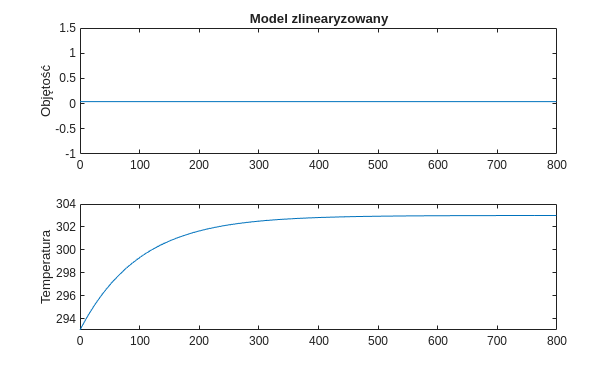

figure()

X_pocz =[0.04; 293];
X_ust = [0.04; 303];
x0 = X_pocz - X_ust;
U = zeros(length(t), length(u));
y = lsim(A,B,C,D,U,t,x0);
subplot(2,1,1),plot(t,y(:,1) + X_ust(1)),title('Model zlinearyzowany'),ylabel('Objętość')
subplot(2,1,2), plot(t,y(:,2) + X_ust(2)), ylabel('Temperatura')

Obliczenia dla modelu nieliniowego, przy nowym wektorze stanu wyznaczonym przy użyciu funkcji trim:

wi = u(1);
w = u(2);
Ti = u(3);
Q = u(4);
[t,xx] = ode45(@zbiornik_stan, [0:799], [V0,T0], [], wi, w, Ti, Q);


Porównanie wykresu z modelem rzeczywistym i zlinearyzowanym. Jak można zauważyć na poniższym wykresie wraz z wzrostem odległości od punktu w stanie ustalonym błąd zaczyna rosnąć. Oczywiście w tym przypadku są to bardzo małe wartości rzędu jednej tysięcznej stopnia Kelwina. Natomiast trzeba być świadomym tego zjawiska i nie pozwalać sobie na symulacje modelu w zbyt dużej odległości od punktu, w którym został on zlinearyzowany.

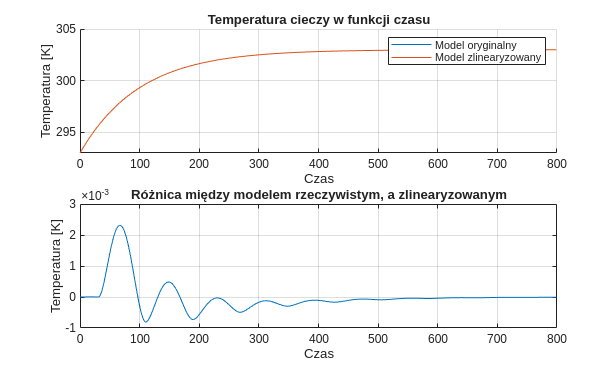

figure()
subplot(2,1,1)
hold on
plot(t,y(:,2) + X_ust(2)), 
plot(t, xx(:,2))
title("Temperatura cieczy w funkcji czasu")
ylabel('Temperatura [K]')
xlabel("Czas")
grid on
legend("Model oryginalny", "Model zlinearyzowany")
hold off

subplot(2,1,2)
plot(t, xx(:,2)- (y(:,2) + X_ust(2)))
title("Różnica między modelem rzeczywistym, a zlinearyzowanym")
xlabel("Czas")
grid on
ylabel('Temperatura [K]')

Kolejnym etapem laboratorium było przeprowadzenie podobnych obliczeń, natomiast tym razem z przyjęciem parametrów:

wi = 0.5 i w = 0.4. Wyniki symulacji przedstawiono w poniższym kodzie:

X_pocz =[0.04; 293];
X_ust = [0.04; 303];
x0 = X_pocz - X_ust;
U = zeros(length(t), length(u));

W tym jednak przypadku, zmienia się parametr wi, dlatego, zmieniono wektor U podawany do funkcji lsim, która odpowiada za symulację

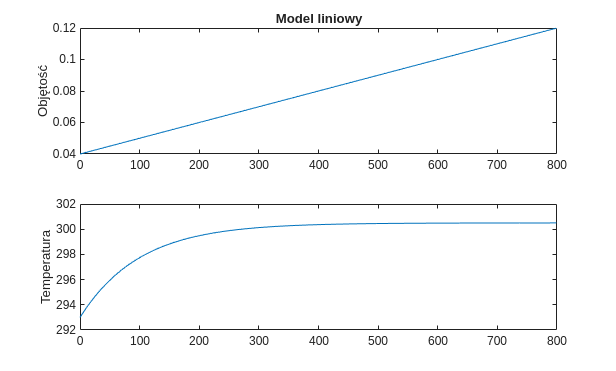

wi = 0.5;
U(:,1) = wi - u(1);
y = lsim(A,B,C,D,U,t,x0);
subplot(2,1,1),plot(t,y(:,1) + X_ust(1)),title('Model liniowy'),ylabel('Objętość')
subplot(2,1,2), plot(t,y(:,2) + X_ust(2)), ylabel('Temperatura')

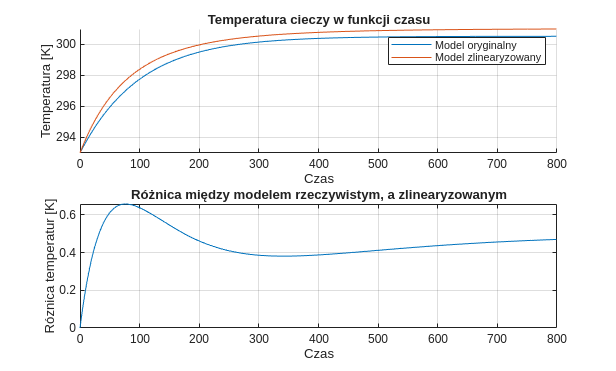

wi = 0.5;
w = u(2);
Ti = u(3);
Q = u(4);
[t,xx] = ode45(@zbiornik_stan, [0:799], [V0,T0], [], wi, w, Ti, Q);

figure()
subplot(2,1,1)
hold on
plot(t,y(:,2) + X_ust(2)), 
plot(t, xx(:,2))
title("Temperatura cieczy w funkcji czasu")
ylabel('Temperatura [K]')
xlabel("Czas")
grid on
legend("Model oryginalny", "Model zlinearyzowany")
hold off

subplot(2,1,2)
plot(t, xx(:,2)- (y(:,2) + X_ust(2)))
title("Różnica między modelem rzeczywistym, a zlinearyzowanym")
xlabel("Czas")
grid on
ylabel('Róznica temperatur [K]')

W stanie nieustalonym, gdy więcej wody wpływa do zbiornika niż z niego wypływa, bład spowodowany linearyzacją modelu staje się coraz to bardziej znaczący. Jak można zauważyć po powyższych wykresach.W obu symulacjach ciecz w zbiorniku nie jest w stanie osiągnąć zadanej temperatury, natomiast dla modelu liniowego temperatura cieczy jest bliższa temperaturze zadanej. Ciekawym spostrzeżeniem jest fakt, że błąd między modelami nie maleje do zera tylko utrzymuje się na dość wysokim poziomie w porównaniu do wcześniej rozważanego problemu.

# Wnioski

Podczas laboratorium przeprowadzono symulację i linearyzację nieliniowego modelu zbiornika. Wykorzystano metodę Rungego-Kutty do symulacji modelu nieliniowego oraz funkcje `trim` i `linmod` do wyznaczenia punktu ustalonego i linearyzacji układu. Wykazano, że linearyzacja jest dokładna jedynie w pobliżu punktu pracy – im dalej od niego, tym większe odchylenie wyników modelu liniowego od nieliniowego. Przy małych zmianach parametrów różnice były minimalne, ale w przypadku większych zmian, oraz przy dynamicznym zachowaniu modelu, błędy wzrastały odpowiednio proporcjonalnie, co widoczne było na wykresach. Zauważono, że model liniowy nie zawsze odwzorowuje rzeczywiste zachowanie układu, co może prowadzić do błędnych wniosków, jeśli odchylenia są znaczne. Linearyzacja jest więc użyteczna do analizy blisko punktu pracy, lecz wymaga ostrożności przy większych zmianach warunków wejściowych.